unmatched = load("17-Oct-2024 190135绘图结果.mat");
NTun = unmatched.NormT;
PAun = unmatched.PAmpilfied;
matched = load("17-Oct-2024 191327绘图结果.mat");
NTma = matched.NormT;
PAma = matched.PAmpilfied;
un2matched = load("17-Oct-2024 193144绘图结果.mat")'

un2matched = 包含以下字段的 struct :
         NormT: [0.0263 0.0527 0.0790 0.1053 0.1316 0.1580 0.1843 0.2106 0.2370 0.2633 0.2896 0.3159 0.3423 0.3686 0.3949 0.4213 0.4476 0.4739 0.5002 0.5266 0.5529 0.5792 0.6056 0.6319]
    PAmpilfied: [1 0.9967 0.9890 0.9776 0.9632 0.9470 0.9310 0.9175 0.9089 0.9056 0.9072 0.9127 0.9216 0.9331 0.9466 0.9616 0.9773 0.9931 1.0082 1.0219 1.0336 1.0426 1.0488 1.0518]


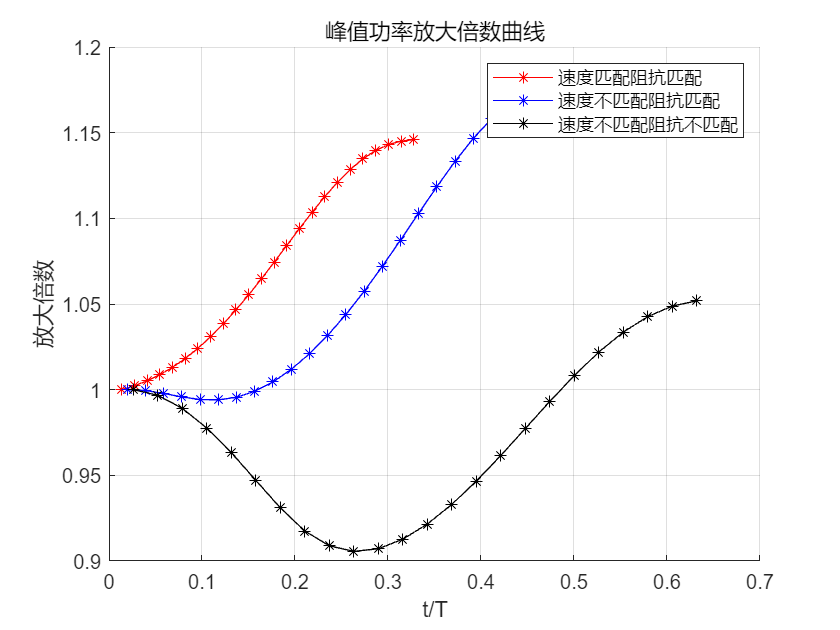

NTun2 = un2matched.NormT;
PAun2 = un2matched.PAmpilfied;

figure;
hold on
plot(NTma,PAma, 'Color', 'r', 'Marker', '*')
plot(NTun,PAun, 'Color', 'b', 'Marker', '*')
plot(NTun2,PAun2, 'Color', 'k', 'Marker', '*')
xlabel('t/T')
ylabel('放大倍数')
title('峰值功率放大倍数曲线')
grid on
legend('速度匹配阻抗匹配', '速度不匹配阻抗匹配', '速度不匹配阻抗不匹配')